Esercizio 1.

Genero il numero pseudo casuale

clc;
n = 1;
while(mod(n, 3) ~= 0)
    n = randi([10, 50], 1);
end
m = n / 3;

% y è una colonna e m righe
y = zeros(m, 1);
% D1 è m colonne e m righe (es. 12/3 = 4)
D1 = 1 * ones(m);
% D3 è 12 (colonne totali) - 4 (sarebbe D1) - 1 = 7
D3 = 3 * ones(m, n - m - 1);

% è una matrice 1x1
D2 = 2 * ones(1, 1);

% D4 è una matrice da una riga e n - m - 1 colonne
D4 = 4 * ones(1, n - m - 1);

% Matrice quadrata da n - m - 1
D5 = 5 * ones(n - m - 1, n - m - 1);

D = [D1, y, D3;
     y', D2, D4;
     D3', D4', D5]

D =      1     1     1     1     1     1     1     1     0     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3
     1     1     1     1     1     1     1     1     0     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3
     1     1     1     1     1     1     1     1     0     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3
     1     1     1     1     1     1     1     1     0     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3
     1     1     1     1     1     1     1     1     0     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3
     1     1     1     1     1     1     1     1     0     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3
     1     1     1     1     1     1     1     1     0     3     3     3     3     3     3     3     3     3     3     3     3

clc;
clear;

Esercizio 2.

Creo la matrice dei coefficienti

k = 1;
err = zeros(1, 10);
for i = 10 : 10 : 100

Il range è da -5 a 10, quindi creando numeri reali tra 0 e 1 devo moltiplicarli per 15

    A = 15 * rand(i) - 5;

Ax = b

Soluzione nota = x[-5, ..., -5]'

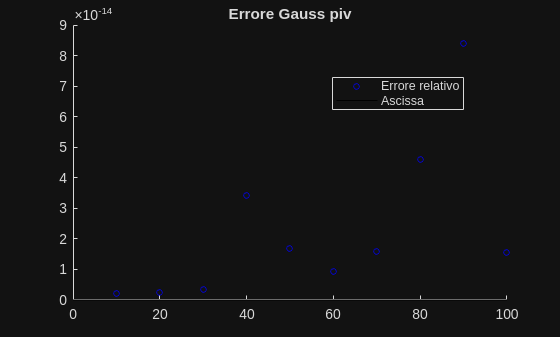

    x = -5 * ones(i, 1);
    b = A * x;
    [U, b1] = gauss_piv(A, b);
    x1 = U \ b1;
    err(k) = norm(x - x1) / norm(x1);

    k = k + 1;

end

hs = 10 : 10 : 100;

x = linspace(0, 100, 100);
figure;
hold on;

title("Errore Gauss piv");
plot(hs, err, "Ob", "DisplayName", "Errore relativo", "MarkerSize", 4);
plot(x, zeros(size(x)), "-k", "DisplayName", "Ascissa", "MarkerSize", 4);
legend('Location', 'best');
hold off;

Esercizio 3.

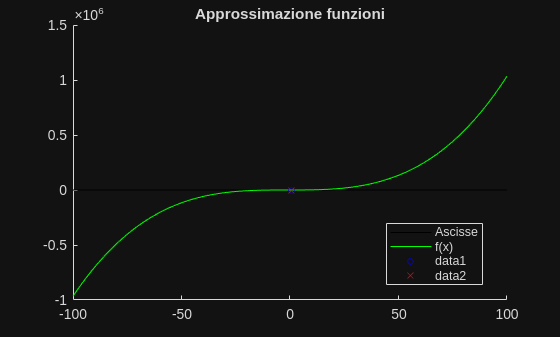

clc
clear

f = @(x) (x - 0.5).*(x + 2).*(x + 2);
f1 = @(x) (x + 2).*(x + 2 .* x + 1);


[xc, kc] = corde(f, f1(1), 1, 10e-5, 100);
[xn, kn] = newton(f, f1, 1, 10e-5, 100);


x = linspace(-100, 100, 100);

figure;
hold on;
title("Approssimazione funzioni");
plot(x, zeros(size(x)), "-k", "DisplayName", "Ascisse");
plot(x, f(x), "-g", "DisplayName", "f(x)");
plot(xn, f(xn), "Ob", "MarkerSize", 4);
plot(xc, f(xc), "xr", "MarkerSize", 6);
legend('Location', 'best');
hold off;

function [U, b2] = gauss_piv(A, b)
    [m, n] = size(A);
    if m ~= n
        error("la matrice deve essere quadrata");
    end

    if size(b, 1) ~= n || size(b, 2) ~= 1
        error("b deve essere un vettore colonna con n righe");
    end

    if abs(det(A)) < 1e-10
        error("La matrice A è singolare");
    end

    for k = 1 : n-1

        % ~ significa "prendi l'output e scartalo
        [~, pos] = max(abs(A(k:n,k))); %Prendo le righe da k in giù nella colonna corrente
        % In pratica scarto il valore e prendo solo la posizione

        % Però ho il valore nel vettore che sto considerando, non della
        % matrice originale:
        l = pos + k - 1;

        % E poi scambio le righe:
        % Prendi la riga k E la riga l
        A([k l], :) = A([l k], :);
        b([k l]) = b([l k]);

        for i = k+1 : n
            m = A(i, k) / A(k, k);

            A(i, :) = A(i, :) - m * A(k, :);

            b(i) = b(i) - m * b(k);
        end
    end
    U = A;
    b2 = b;
end

function [xn, kn] = newton(f, fder, x0, tau, kmax)
    kn = 1;
    xn = -1;
    f1 = fder(x0);

    if(abs(f(x0)) < tau)
        xn = x0;
        return;
    end

    while(kn < kmax && abs(f(xn)) >= tau)
        
        if(abs(f1) < tau)
            error("Cambia x0");
        end

        xn = x0 - f(x0) / f1;
        
        x0 = xn;
        f1 = fder(x0);

        kn = kn + 1;
    end
end

function [x, k] = corde(fun, m, x0, tol, kmax)
    
    k = 0;
    if (abs(fun(x0)) < tol)
        x = x0;
        return
    end

    x_new = x0;
    flag = 1;
    while flag
        k = k + 1;
        xk = x_new;
        fk = fun(xk);

        x_new = xk - fk / m;

        
        flag = (abs(x_new - xk) > abs(xk) * tol) && (k < kmax) && abs(fun(x_new)) > tol;

    end

    if k >= kmax
        warning("Raggiunto kmax");
        x = inf;
    else
        x = x_new;
    end

end